clear all

t = (0:0.01:0.99)'

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


rng(1)
timesteps = 20

timesteps = 20


t=linspace(0,1,timesteps+1)'

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


t(end)=[];

M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

knots = 4

knots = 4

index= [];

output1 = sin(exp(t)+sin(10*t).^2+3*cos(3*t)+0.5*rand(timesteps,1));
output2= cos(5*t)+0.5*rand(timesteps,1)

output2 =     1.4004
    1.4530
    1.0343
    1.0779
    0.9785
    0.7626
    0.1133
   -0.1587
   -0.3312
   -0.1891



output_curve = outproduct(output1,output2);

Y = output_curve(:)

Y =    -1.2263
   -1.3927
   -1.3996
   -1.3391
   -1.3912
   -0.9462
   -0.2592
   -0.0924
   -0.2898
   -0.4255


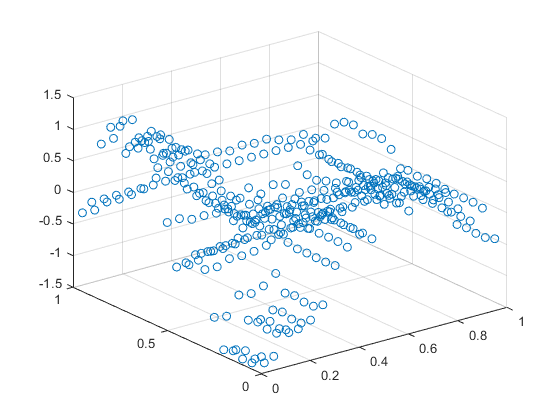



[X,Z] = meshgrid(t,t);

scatter3(X(:),Z(:),Y)

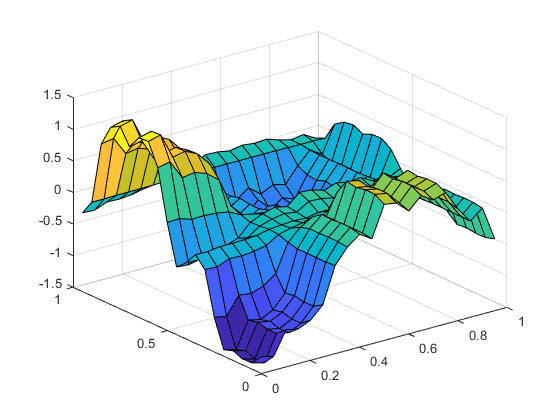


% output_curve(1:80,1:80)=0
surf(t,t,output_curve);

% 
% plot(output1)
% plot(output2)

N=zeros(length(t),knots+2);
B=[]


B =

     []



C=[]


C =

     []




for i=1:length(t)
   index(i)= floor((t(i)*knots+(10*knots*eps)))+1;
    Ntemp = (mod(t(i),1/knots)*knots).^linspace(2,0,3)*M';
%     Ntemp = (t(i)-(index(i)-1)/timesteps/knots).^linspace(2,0,3)*M';
    N(i,index(i):index(i)+2) = Ntemp;
end

for ii= 1:timesteps
    for jj=1:timesteps

N_multi = outproduct(N(ii,:),N(jj,:));
   B(jj,:)=N_multi(:)';
    end
    C = [C ; B];
end


% -------------------------------------
tic
Theta=zeros(36,1)

Theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Pcov =eye(36)*1000

Pcov =         1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0        1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0           0        1000           0           0           0           0           0           0           0       



for kk=1:400
    
Phi = C(kk,:);

Pcov = Pcov - (Pcov * Phi'*Phi * Pcov)/(1+Phi*Pcov*Phi');

epsil = Y(kk) - Phi * Theta;

K = Pcov*Phi';
Theta = Theta + K *epsil;

end
toc

Elapsed time is 0.081906 seconds.


% -----------------------------------
tic
P=pinv(C)*output_curve(:) ;
toc

Elapsed time is 0.008838 seconds.


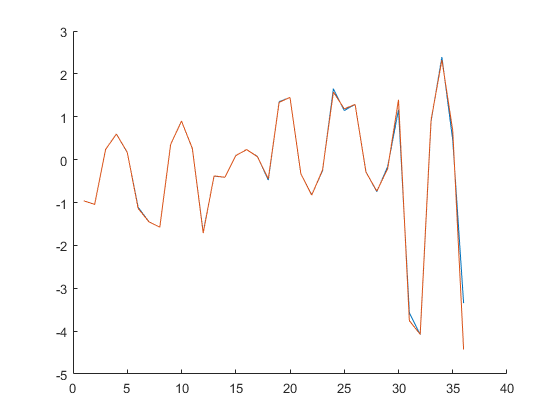


y=C*P;
% y=C*Theta;

figure;
hold on
plot(Theta)
plot(P)
hold off

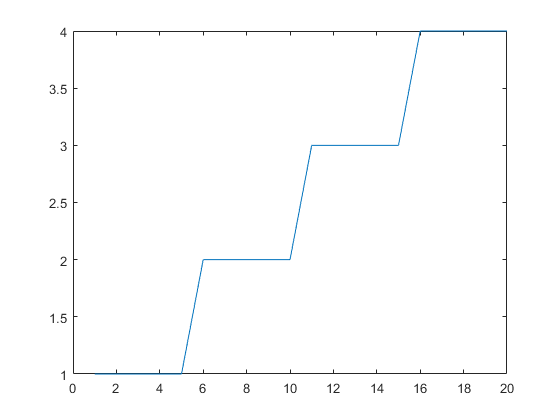


plot(index)

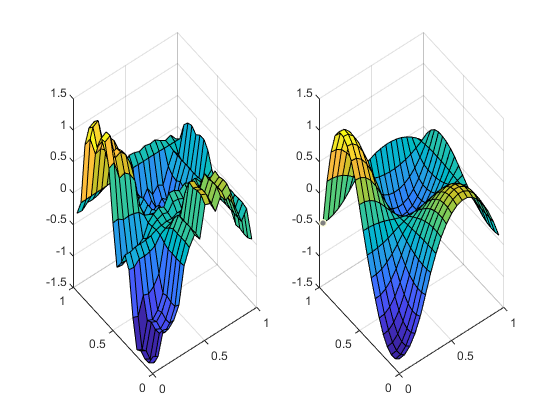


subplot(1,2,1);
surf(t,t,output_curve)

subplot(1,2,2);
surf(t,t,reshape(y,[timesteps timesteps]))

% 
% surf(1:knots+2,1:knots+2,reshape(P,[knots+2 knots+2]))
% 
% norm(reshape(y,[timesteps timesteps])-output_curve)
% 
% % surf(t,t,abs(reshape(y,[timesteps timesteps])-output_curve))



[coeff,score,latent] = pca(reshape(P,[knots+2 knots+2]))

coeff =     0.2129    0.9145    0.1235   -0.3114   -0.0496
    0.3209   -0.2194    0.8527   -0.0294   -0.3478
    0.0838   -0.0105    0.2411   -0.1196    0.6674
   -0.2954    0.3172    0.2893    0.8330    0.1682
   -0.2620    0.1220   -0.1171    0.0954   -0.6319
    0.8299    0.0027   -0.3197    0.4299   -0.0598


score =    -2.8512    0.0000   -0.0000   -0.0000    0.0000
   -3.2369   -0.0000    0.0000    0.0000    0.0000
    2.7851    0.0000   -0.0000   -0.0000   -0.0000
    4.4749   -0.0000    0.0000   -0.0000    0.0000
    2.4886    0.0000   -0.0000    0.0000    0.0000
   -3.6605   -0.0000   -0.0000    0.0000    0.0000


latent =    13.1962
    0.0000
    0.0000
    0.0000
    0.0000


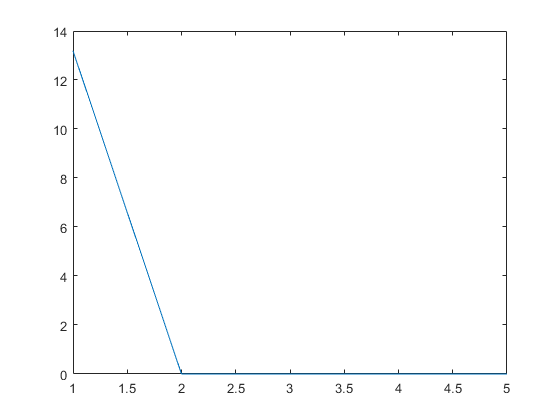


plot(latent)